clc; clear; close all;

% Choosing file path for the data
[chosenfile,chosendirectory] = uigetfile({'*.xlsx';'*.csv'},...
            'Select Excel time series Data sets','data.xlsx');

filePath = [chosendirectory chosenfile];

% Loading the data into a series array of doubles
seriesData = readtable(filePath);
seriesData = table2array(seriesData(:,:));

% Converting into 5 day observation periods throughout the year
interval = 5; % Interval in minutes
minutes_per_day = 1440; % Total minutes in a day
obs_duration = 1 * minutes_per_day; % Observation duration in minutes (3 days)
obs_length = obs_duration / interval; % Number of data points per observation (4320)
num_obs = floor(length(seriesData) / obs_length); % Total number of 3-day observations

% Preallocate cell array
data = cell(num_obs, 1);

% Populate cell array with 3-day segments
for i = 1:num_obs
    startIdx = (i - 1) * obs_length + 1;
    endIdx = i * obs_length;
    data{i} = seriesData(startIdx:endIdx);
end

% Checking the data is in the correct format for training
numChannels = size(data{1},2);

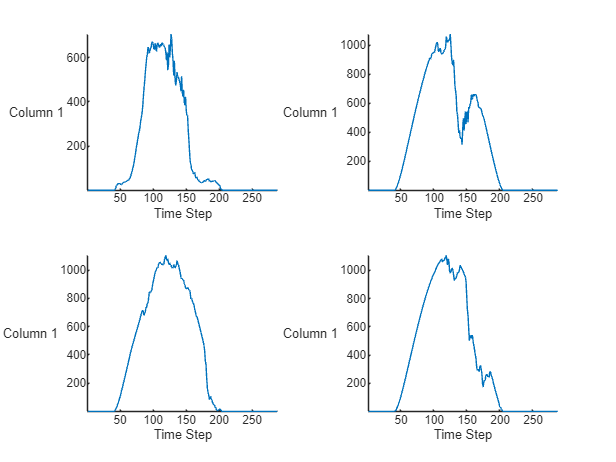


figure
tiledlayout(2,2)
for i = 1:4
    nexttile
    stackedplot(data{i})

    xlabel("Time Step")
end

% Splitting the data into training and testing segments
trainingRatio = 0.9;
numObservations = numel(data);

idxTrain = 1:floor(trainingRatio*numObservations);
idxTest = floor(trainingRatio*numObservations)+1:numObservations;

dataTrain = data(idxTrain);
dataTest = data(idxTest);

% Preparing the data for training
numObservationsTrain = numel(dataTrain);
XTrain = cell(numObservationsTrain,1);
TTrain = cell(numObservationsTrain,1);

for n = 1:numObservationsTrain
    X = dataTrain{n};
    XTrain{n} = X(1:end-1,:);
    TTrain{n} = X(2:end,:);
end

% normalising the sequences to reduce the change of divergence
muX = mean(cell2mat(XTrain))

muX = 266.1763

sigmaX = std(cell2mat(XTrain),0)

sigmaX = 351.2530


muT = mean(cell2mat(TTrain));
sigmaT = std(cell2mat(TTrain),0);

for n = 1:numel(XTrain)
    XTrain{n} = (XTrain{n} - muX) ./ sigmaX;
    TTrain{n} = (TTrain{n} - muT) ./ sigmaT;
end

% Defining LSTM Architecture
layers = [
    sequenceInputLayer(numChannels)
    lstmLayer(128)
    fullyConnectedLayer(numChannels)];

options = trainingOptions("adam", ...
    MaxEpochs=200, ...
    SequencePaddingDirection="left", ...
    Shuffle="every-epoch", ...
    Plots="training-progress", ...
    Verbose=false);


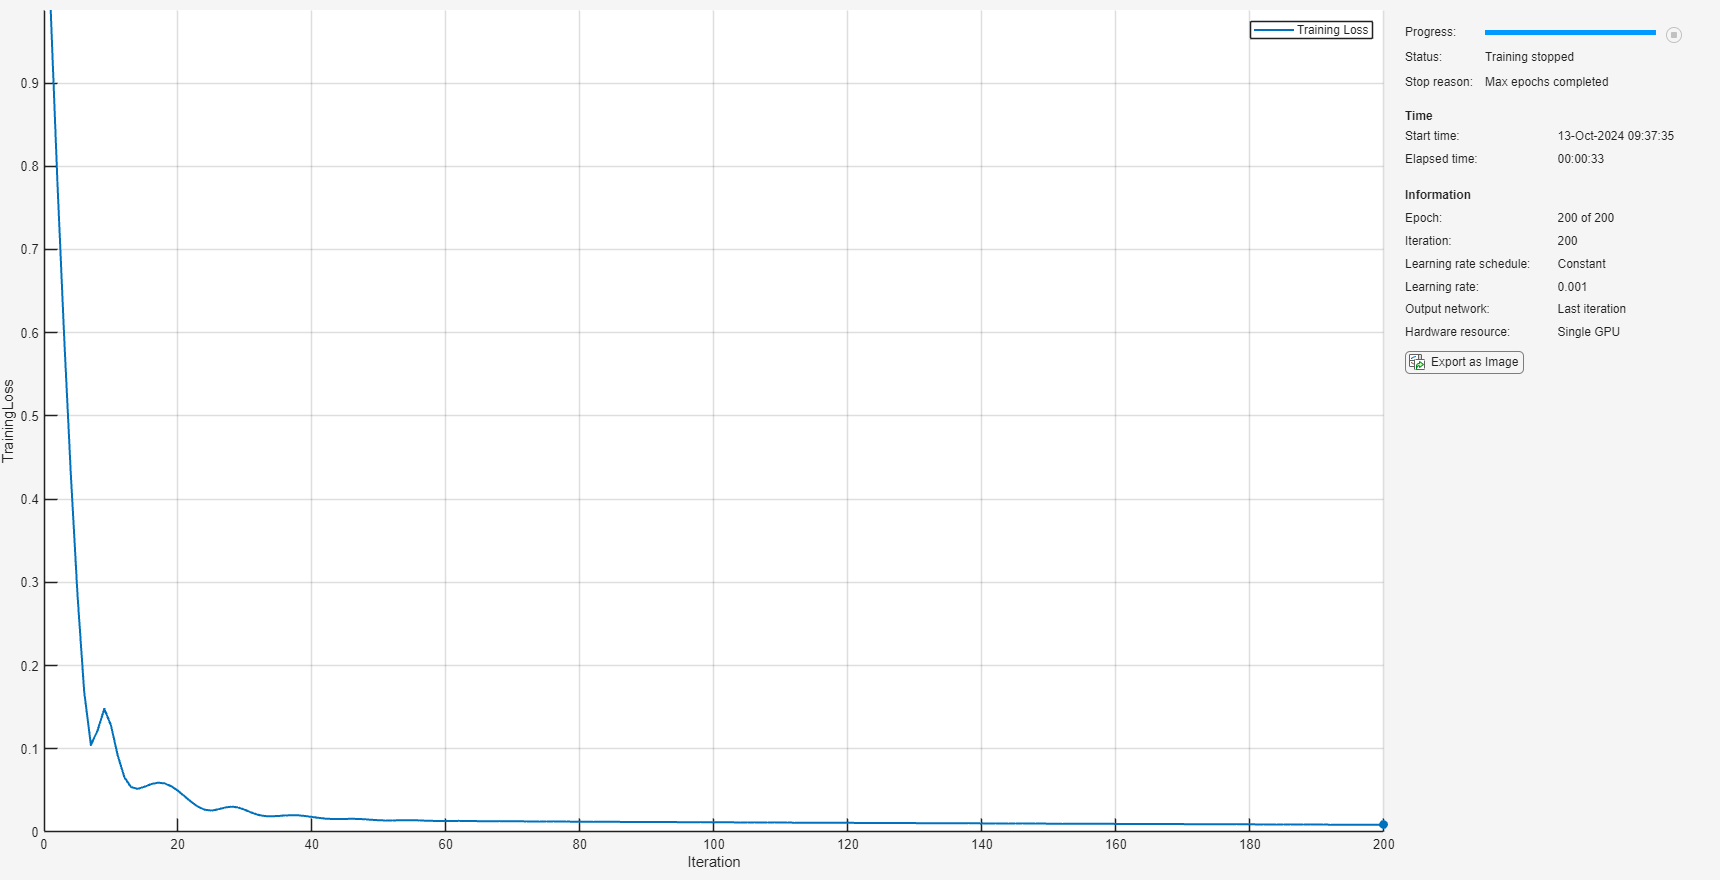

% Training the network (dual bi-lstm layer)
net = trainnet(XTrain,TTrain,layers,"mse",options);

% Saving the trained model
save('NET_LSTM_2023_irradiance','net')

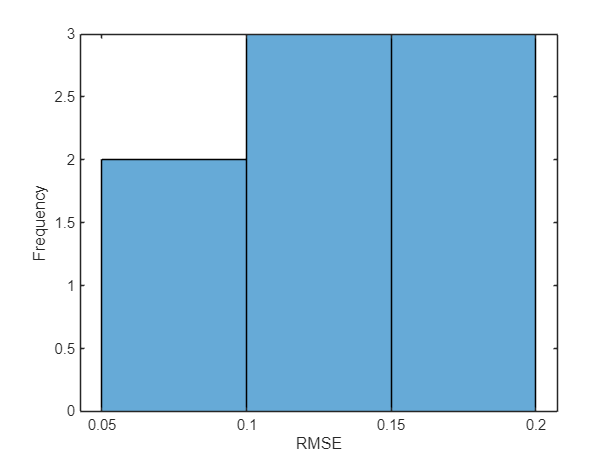

% Testing the trained network net
numObservationsTest = numel(dataTest);
XTest = cell(numObservationsTest,1);
TTest = cell(numObservationsTest,1);
for n = 1:numObservationsTest
    X = dataTest{n};
    XTest{n} = (X(1:end-1,:) - muX) ./ sigmaX;
    TTest{n} = (X(2:end,:) - muT) ./ sigmaT;
end

YTest = minibatchpredict(net,XTest, ...
    SequencePaddingDirection="left", ...
    UniformOutput=false);

for n = 1:numObservationsTest
    T = TTest{n};

    sequenceLength = size(T,1);    

    Y = YTest{n}(end-sequenceLength+1:end,:);

    err(n) = rmse(Y,T,"all");
end

figure
histogram(err)
xlabel("RMSE")
ylabel("Frequency")

mean(err,"all")

ans = single
0.1292

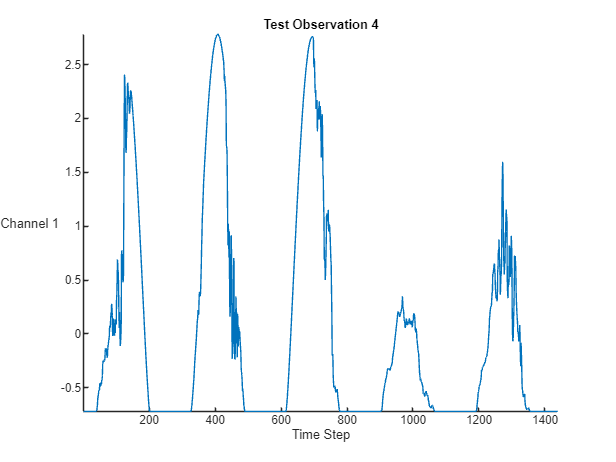

% Open loop forecasting example
idx = 4;
X = XTest{idx};
T = TTest{idx};

figure
stackedplot(X,DisplayLabels="Channel " + (1:numChannels))
xlabel("Time Step")
title("Test Observation " + idx)

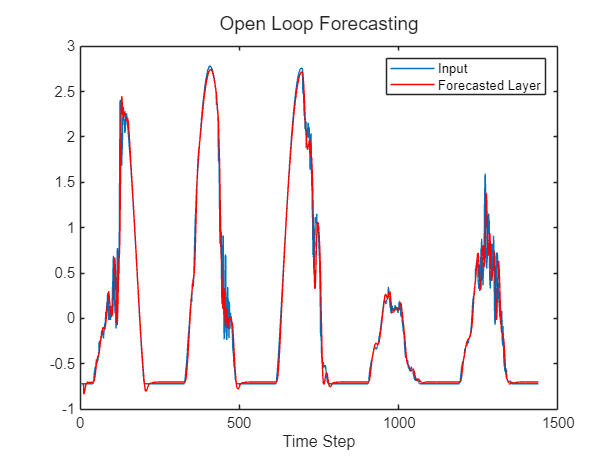

net = resetState(net);
offset = 10;
[Z,state] = predict(net, X(1:offset,:));
net.State = state;

numTimeSteps = size(X,1);
numPredictionTimeSteps = numTimeSteps - offset;
Y = zeros(numPredictionTimeSteps,numChannels);
Y(1,:) = Z(end,1);

for t = 1:numPredictionTimeSteps-1
    Xt = X(offset+t,:);
    [Y(t+1,:),state] = predict(net,Xt);
    net.State = state;
end

figure
t = tiledlayout(numChannels,1);
title(t,"Open Loop Forecasting")

for i = 1:numChannels
    nexttile
    plot(X(:,i))
    hold on
    plot(offset:numTimeSteps,[X(offset,i) Y(:,i)'],"-r")
end

xlabel("Time Step")
nexttile(1)
legend(["Input" "Forecasted Layer"])

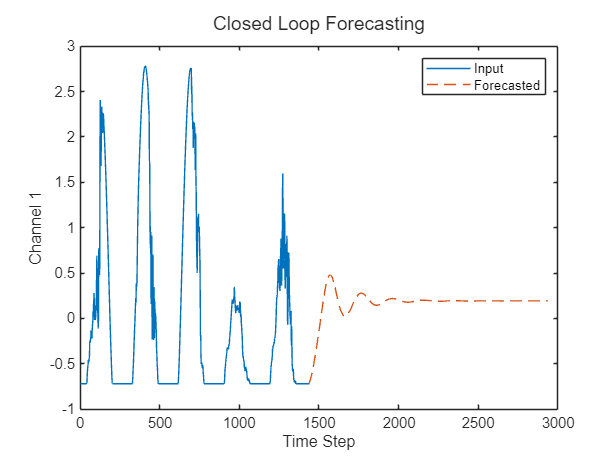

% Closed loop forcasting example
net = resetState(net);
offset = size(X,1);
[Z,state] = predict(net,X(1:offset,:));
net.State = state;

numPredictionTimeSteps = 1500;
Y = zeros(numPredictionTimeSteps,numChannels);
Y(1,:) = Z(end,:);

for t = 2:numPredictionTimeSteps
    [Y(t,:),state] = predict(net,Y(t-1,:));
    net.State = state;
end

numTimeSteps = offset + numPredictionTimeSteps;

figure
t = tiledlayout(numChannels,1);
title(t,"Closed Loop Forecasting")

for i = 1:numChannels
    nexttile
    plot(X(1:offset,i))
    hold on
    plot(offset:numTimeSteps,[X(offset,i) Y(:,i)'],"--")
    ylabel("Channel " + i)
end

xlabel("Time Step")
nexttile(1)
legend(["Input" "Forecasted"])

% Converting test data into time series for simulink
days = 1;
interval = days * 288;
testData = seriesData(1:interval)';

timeVector = (0:5:(interval-1)*5)';  % Generate time points in minutes
timeVector = timeVector * 60;  % Convert to seconds

testDataTimeSeries= timeseries(testData, timeVector);

ts.TimeInfo.Units = 'minutes';



% Generate a random signal using layers of Gaussian noise with varying frequencies and amplitudes
% The signal is 4 hours long (14,400 seconds), sampled every 1 second
% The signal values range between 0 and 1000, covering the entire range with appropriate fluctuations


% Define the time vector for minute intervals
duration_minutes = 10;  % 10 minutes
t_minutes = 0:0.1:duration_minutes;  % Time vector from 0 to 60 minutes at 6-s intervals
nPoints_minutes = length(t_minutes);

% Convert time to seconds
t_minutes_seconds = t_minutes * 60;  % Convert minutes to seconds

% Generate random signal values at minute intervals
% Create a truncated normal distribution to ensure values are between 0 and 1000
lowerBound = 0;
upperBound = 1000;

% Create a normal distribution with the given mean and standard deviation
pd = makedist('Normal', 'mu', muX, 'sigma', sigmaX);

% Truncate the distribution to the [0, 1000] interval
t_dist = truncate(pd, lowerBound, upperBound);

% Generate random numbers from the truncated normal distribution
randomSignal_minutes = random(t_dist, nPoints_minutes, 1);

% Define the finer time vector at 1-second intervals
duration_seconds = duration_minutes * 60;  % Total duration in seconds
t_seconds = 0:1:duration_seconds;  % Time vector from 0 to duration in seconds at 1-second intervals

% Perform spline interpolation to get the signal at 1-second intervals
randomSignal_seconds = spline(t_minutes_seconds, randomSignal_minutes, t_seconds);

% Ensure the interpolated signal stays within [0, 1000]
randomSignal_seconds(randomSignal_seconds < 0) = 0;
randomSignal_seconds(randomSignal_seconds > 1000) = 1000;

% Create a timeseries object for the interpolated signal
ts_randomSignal = timeseries(randomSignal_seconds, t_seconds);
ts_randomSignal.Name = 'Generated Random Signal';
ts_randomSignal.TimeInfo.Units = 'seconds';

save('ts_randomSignal4', 'ts_randomSignal')

load('ts_randomSignal2', 'ts_randomSignal')

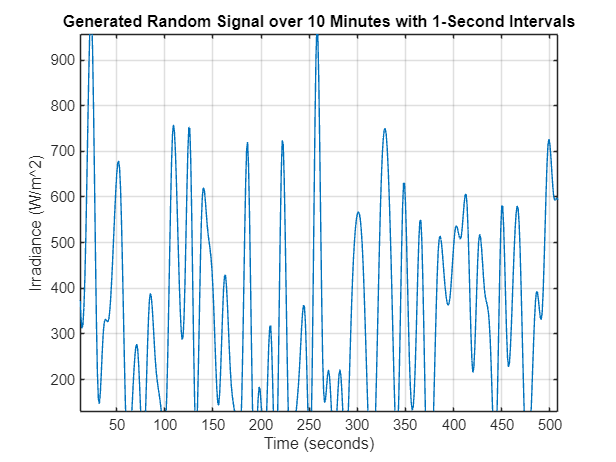

% Optional: Plot the original minute-interval data and the interpolated signal
figure;
plot(ts_randomSignal);
xlabel('Time (seconds)');
ylabel('Irradiance (W/m^2)');
title('Generated Random Signal over 10 Minutes with 1-Second Intervals');
grid on;


% Assuming t_seconds and randomSignal_seconds are given and t_seconds is increasing
% First, define the 5-minute interval edges
t_min = t_seconds(1);
t_max = t_seconds(end);

% 5 minutes in seconds
interval_duration = 300;

% Generate interval edges starting from t_min to t_max with steps of 300 seconds
interval_edges = t_min:interval_duration:t_max;

% Ensure the last interval includes t_max
if interval_edges(end) < t_max
    interval_edges = [interval_edges, t_max];
end

% Use 'discretize' to assign each time point to an interval bin
bin_indices = discretize(t_seconds, interval_edges);

% Number of intervals
num_intervals = length(interval_edges) - 1;

% Initialize a cell array to store the signal segments
segments = cell(1, num_intervals);

% Loop over each interval and extract the corresponding signal segment
for i = 1:num_intervals
    % Find indices of t_seconds that fall into the current interval
    indices = bin_indices == i;
    % Extract the signal segment for the current interval
    segments{i} = randomSignal_seconds(indices);
end


for i = 1:num_intervals
    % Find indices of t_seconds that fall into the current interval
    indices = bin_indices == i;
    % Extract the signal segment for the current interval
    segments{i} = randomSignal_seconds(indices);
end

t_seconds_5min = 0:1:299;


% Create a timeseries object for the interpolated signal
ts_randomSignal1 = timeseries(segments{1} , t_seconds_5min);
ts_randomSignal1.TimeInfo.Units = 'seconds';

% Create a timeseries object for the interpolated signal
ts_randomSignal2 = timeseries(segments{2} , t_seconds_5min);
ts_randomSignal2.TimeInfo.Units = 'seconds';

% Create a timeseries object for the interpolated signal
ts_randomSignal3 = timeseries(segments{3} , t_seconds_5min);
ts_randomSignal3.TimeInfo.Units = 'seconds';

% Create a timeseries object for the interpolated signal
ts_randomSignal4 = timeseries(segments{4} , t_seconds_5min);
ts_randomSignal4.TimeInfo.Units = 'seconds';

% Create a timeseries object for the interpolated signal
ts_randomSignal5 = timeseries(segments{5} , t_seconds_5min);
ts_randomSignal5.TimeInfo.Units = 'seconds';

% Create a timeseries object for the interpolated signal
ts_randomSignal6 = timeseries(segments{6} , t_seconds_5min);
ts_randomSignal6.TimeInfo.Units = 'seconds';

% Create a timeseries object for the interpolated signal
ts_randomSignal7 = timeseries(segments{7} , t_seconds_5min);
ts_randomSignal7.TimeInfo.Units = 'seconds';

% Create a timeseries object for the interpolated signal
ts_randomSignal8 = timeseries(segments{8} , t_seconds_5min);
ts_randomSignal8.TimeInfo.Units = 'seconds';

% Create a timeseries object for the interpolated signal
ts_randomSignal9 = timeseries(segments{9} , t_seconds_5min);
ts_randomSignal9.TimeInfo.Units = 'seconds';

% Create a timeseries object for the interpolated signal
ts_randomSignal10 = timeseries(segments{10} , t_seconds_5min);
ts_randomSignal10.TimeInfo.Units = 'seconds';

% Create a timeseries object for the interpolated signal
ts_randomSignal11 = timeseries(segments{11} , t_seconds_5min);
ts_randomSignal11.TimeInfo.Units = 'seconds';

% Create a timeseries object for the interpolated signal
ts_randomSignal12 = timeseries(segments{12}(1:300) , t_seconds_5min);
ts_randomSignal12.TimeInfo.Units = 'seconds';

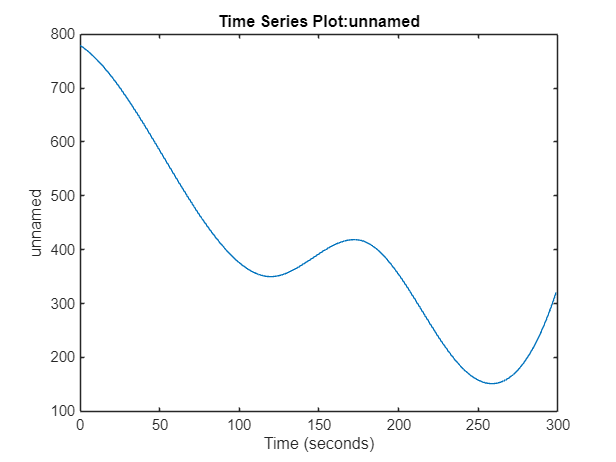


figure
tiledlayout(6,6)
plot(ts_randomSignal1)

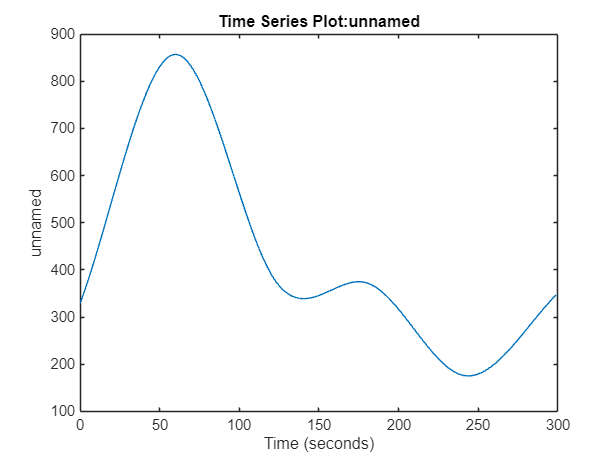

plot(ts_randomSignal2)

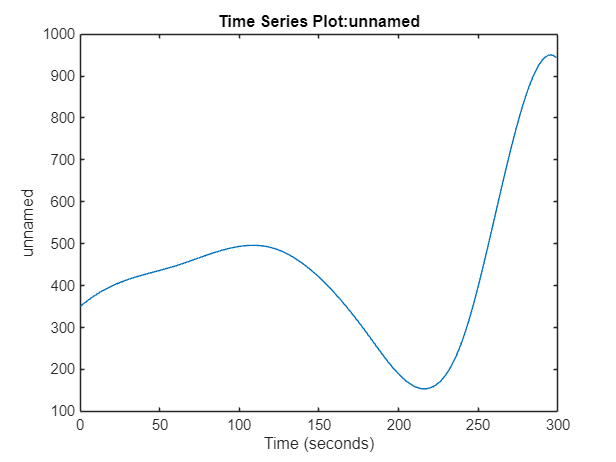

plot(ts_randomSignal3)

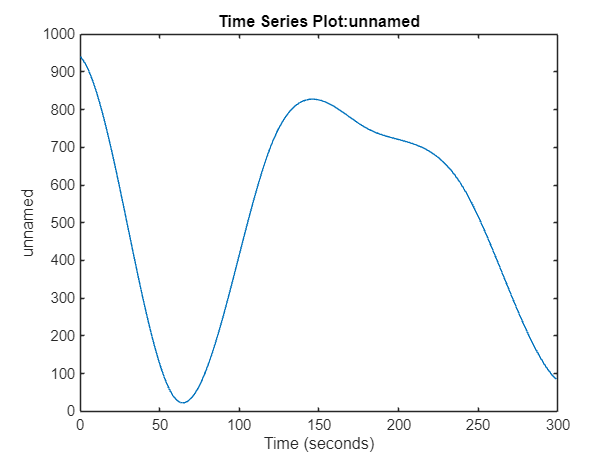

plot(ts_randomSignal4)

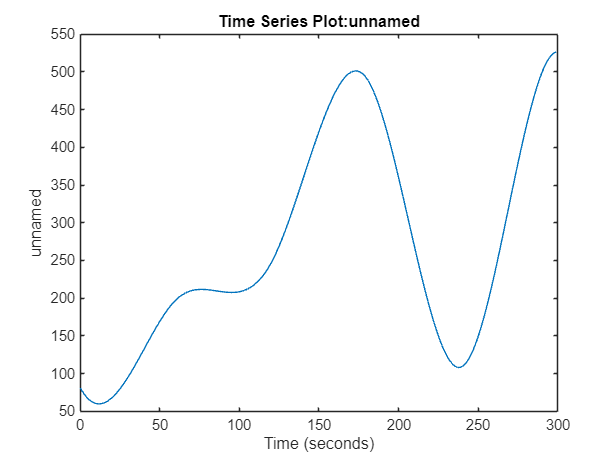

plot(ts_randomSignal5)

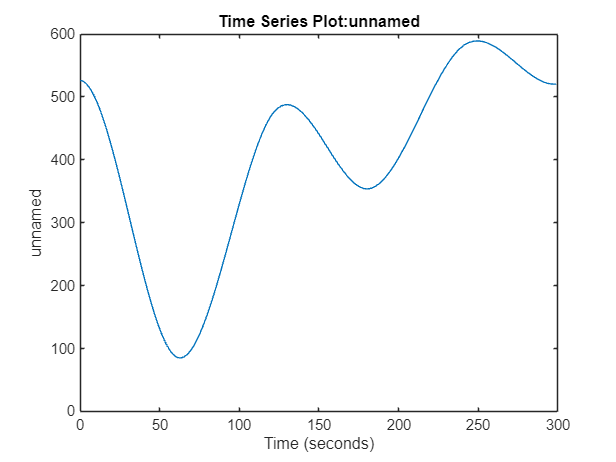

plot(ts_randomSignal6)

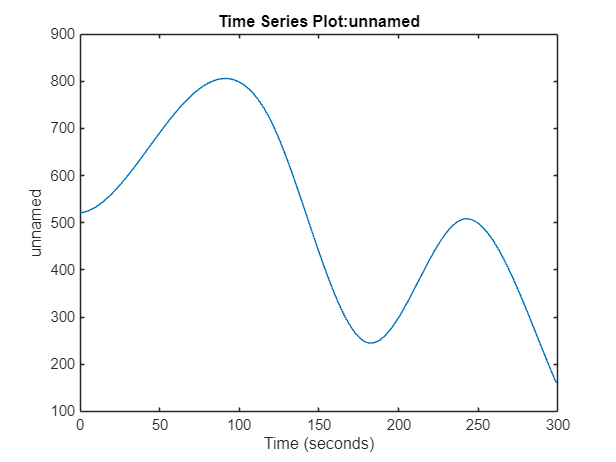

plot(ts_randomSignal7)

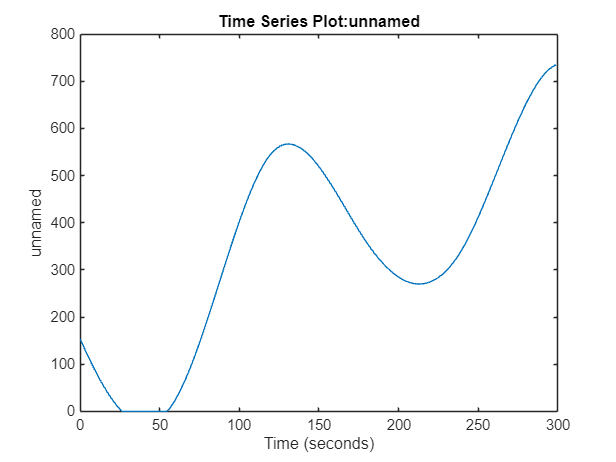

plot(ts_randomSignal8)

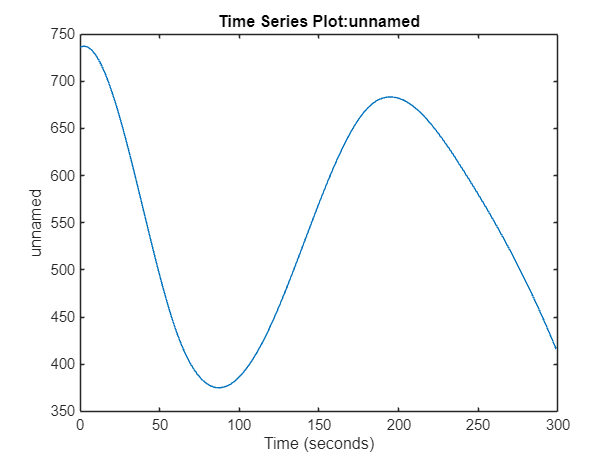

plot(ts_randomSignal9)

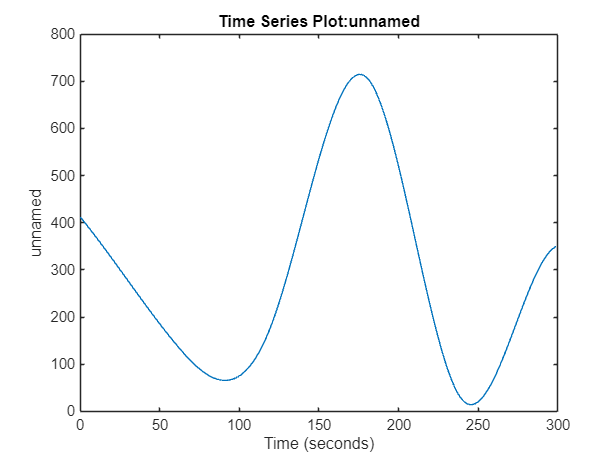

plot(ts_randomSignal10)

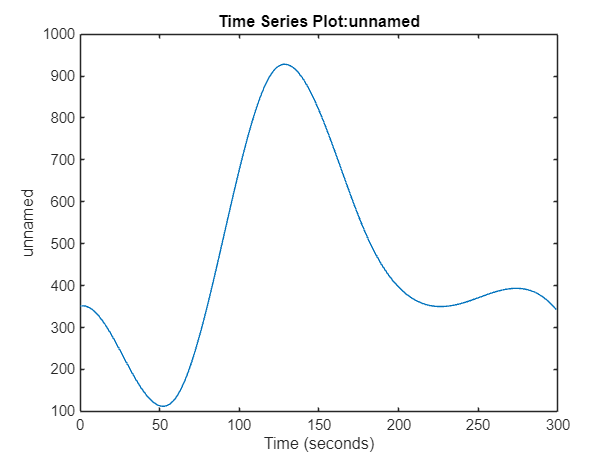

plot(ts_randomSignal11)

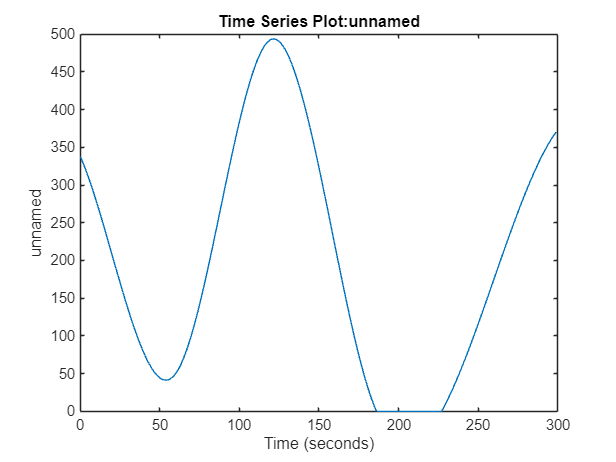

plot(ts_randomSignal12)

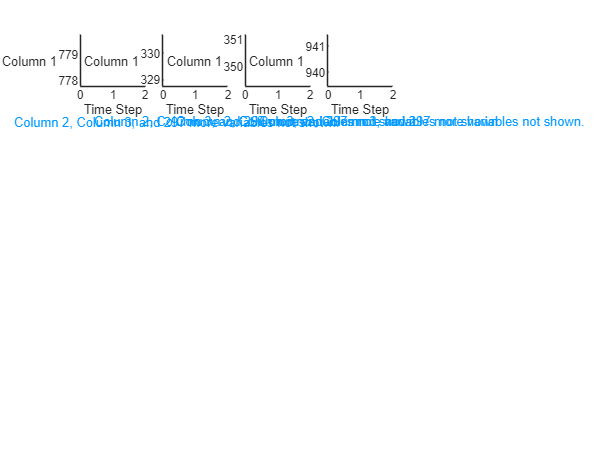

figure
tiledlayout(6,6)
for i = 1:4
    nexttile
    stackedplot(segments{i})

    xlabel("Time Step")
end